# Visualizing Artifact Data from the Excavations at Polis

Data set obtained from [Open Context](https://opencontext.org/search/Cyprus?q=polis#10/35.0349/32.4218/20/any/Google-Satellite)

% Imports from the data set the seven columns that can be best visualized
ImportPolisData;

## Visualizing Artifact Material Types

For this section regarding material type: An initial missing data clean is performed. From there, many of the remaining data points are cleaned to present a more general view. For example, "Marble", "Marble - White", and "Marble - Smooth White" were all combined to be a part of the "Marble" category for visualization. Additionally, there is a large count of individual or groups of items not significant enough to graph. Any item category that makes up less than 1% of the total dataset is marked as "Other" for visualization purposes. These items would crowd the visualization, and are easier to make sense of as a list.

### Clean Missing Data

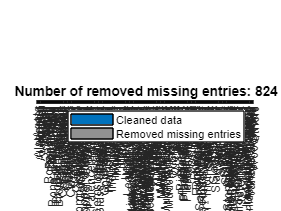

% Remove missing data
[TypeData,missingIndices2] = rmmissing(PolisData,"DataVariables","MaterialType");

% Display results
figure

% Plot cleaned data
histogram(PolisData.MaterialType(~missingIndices2),"ShowOthers","on",...
    "FaceColor",[0 114 189]/255,"FaceAlpha",1,"DisplayName","Cleaned data")
hold on

% Plot removed missing entries
histogram(PolisData.MaterialType(missingIndices2),"ShowOthers","on",...
    "FaceColor",[145 145 145]/255,"FaceAlpha",1,...
    "DisplayName","Removed missing entries")
title("Number of removed missing entries: " + nnz(missingIndices2))

hold off
legend
xlabel("MaterialType")



% Output count of all items within the data set
% summary(TypeData.MaterialType)

% Create initial pie chart
% pie(TypeData.MaterialType)
% xlabel("PartType")
% title("PartType")

### Sort Data by Category 

This is the section responsible for correctly sorting the data into categorical variables based on contained keywords within the cell body. Items that are not linked to a predefined category are sorted into "Other".

% Define array of category keywords
typeCats = ["Terracotta" "Bone" "Carbon" "Bronze" "Ceramic" "Charcoal" "Clay" ...
    "Copper" "Glass" "Iron" "Limestone" "Marble" "Metal" "Plaster" "Shell" "Slag" "Stone"];

TypeData.MaterialType = CategorizeData(TypeData.MaterialType, typeCats);

% Clean removed categories from the set
TypeData.MaterialType = removecats(TypeData.MaterialType);

% Output a final summary
summary(TypeData.MaterialType)

     Bone             6365 
     Bronze           2015 
     Carbon            267 
     Ceramic           636 
     Charcoal         1404 
     Clay             1614 
     Copper            747 
     Glass            4247 
     Iron             1641 
     Limestone        1404 
     Marble            692 
     Metal             492 
     Plaster          2177 
     Shell            3756 
     Slag             4467 
     Stone            1481 
     Terracotta      16372 
     Other            2160 


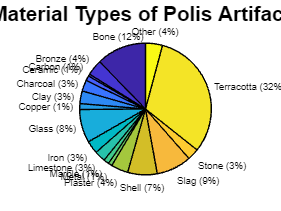


% Generate Pie Chart
pie(TypeData.MaterialType)
title("Material Types of Polis Artifacts",'FontSize',22)
fontsize(gcf,"scale",.70)

## Material Types per Context

Within active archaeological digs, it can be useful to know where to dig next based on the research problem. Visualizing the material distribution from different contexts can make it easier to know where to dig next.

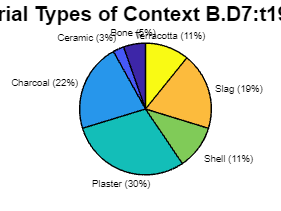

% Select context to visualize from the list
context = 'B.D7:t19-2000';

% Create matrix of containing all data from given context and clean
contextMatrix = TypeData(TypeData.ContextThree == context,:);
contextMatrix.MaterialType = removecats(contextMatrix.MaterialType);

pie(contextMatrix.MaterialType)
title("Material Types of Context " + context,'FontSize',22)
fontsize(gcf,"scale",.70)

## Visualize Artifact Categories

% Define array of category keywords
catCats = ["Architectural Misc" "Architectural Stone" "Architectural Terracotta" "Bone, Ivory, Shell" ...
    "Bronze" "Glass" "Iron" "Miscellaneous Ceramic" "Mosaic Tesserae" "Numismatics" "Organic" "Pottery" ...
    "Slag" "Stone Objects" "Terracotta Figurines" "Terracotta Lamps"];

TypeData.MaterialCategory = CategorizeData(TypeData.MaterialCategory, catCats);

TypeData.MaterialCategory = removecats(TypeData.MaterialCategory);

summary(TypeData.MaterialCategory)

     Architectural Stone            1426 
     Bone, Ivory, Shell            10558 
     Glass                          4193 
     Mosaic Tesserae                1141 
     Numismatics                    1880 
     Slag                           4669 
     Stone Objects                   941 
     Terracotta Lamps                912 
     Other                          1377 
     Pottery                        2129 
     Terracotta Figurines          14335 
     Architectural Terracotta        633 
     Miscellaneous Ceramic           534 
     Architectural Misc             2638 
     Bronze                          865 
     Iron                           1737 
     Organic                        196

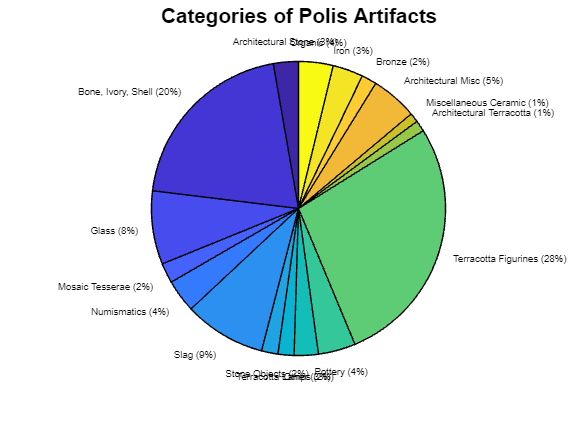


pie(TypeData.MaterialCategory)
title("Categories of Polis Artifacts",'FontSize',22)
fontsize(gcf,"scale",.70)

% Clean Objects and graph objects vs material type

## Sizes of Terracotta Statuettes

This section displays the width vs. height of the terracotta figurines found at the site. Missing data is first cleaned and then a scatter plot is generated. A least-squares line is added to the data plot to display its upward trend. For visualization purposes, the X and Y axes are cut off at 30 as the vast majority of the data falls below these points. Something important to note with this visual is that the data includes both complete artifacts alongside fragmented pieces, which is bound to have some effect on the end result.

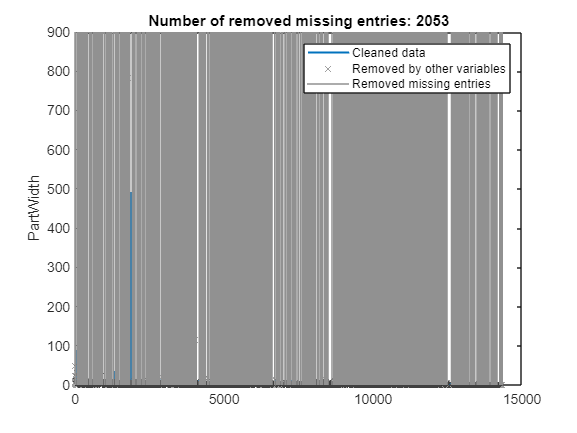

% Create set of terracotta statuettes
statuettes = TypeData(TypeData.MaterialCategory == "Terracotta Figurines",:);
% Remove missing data
[newTable,missingIndices] = rmmissing(statuettes,...
    "DataVariables",["PartWidth","PartThickness","PartHeight"]);

% Display results
figure
% Get locations of missing data
indicesForPlot = ismissing(statuettes.PartWidth);
mask = missingIndices & ~indicesForPlot;

% Plot cleaned data
plot(find(~missingIndices),newTable.PartWidth,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")
hold on

% Plot data in rows where other variables contain missing entries
plot(find(mask),statuettes.PartWidth(mask),"x","Color",[64 64 64]/255,...
    "DisplayName","Removed by other variables")

% Plot removed missing entries
x2 = repelem(find(indicesForPlot),3);
y = repmat([ylim(gca) missing]',nnz(indicesForPlot),1);
plot(x2,y,"Color",[145 145 145]/255,"DisplayName","Removed missing entries")
title("Number of removed missing entries: " + nnz(indicesForPlot))

hold off
legend
ylabel("PartWidth")

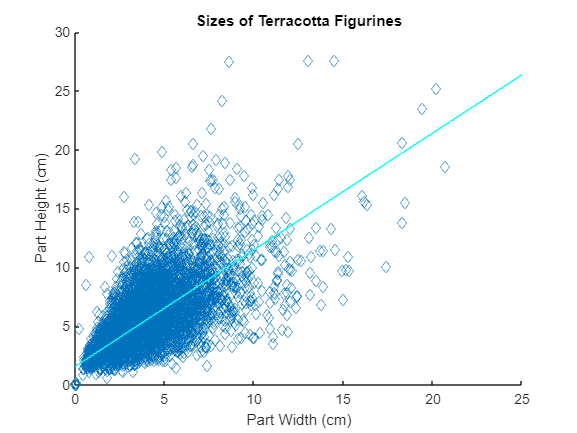

clear indicesForPlot mask x2 y
newTable = newTable(newTable.PartWidth < 30,:);
newTable = newTable(newTable.PartHeight < 30,:);

%newTable = rmoutliers(newTable.PartWidth);
%newTable = rmoutliers(newTable.PartHeight);


s = scatter(newTable.PartWidth,newTable.PartHeight);
line = lsline;
title("Sizes of Terracotta Figurines")
xlabel("Part Width (cm)")
ylabel("Part Height (cm)")
line.Color = 'c';
s.Marker = "diamond";

function toCategorize = CategorizeData(toCategorize, categories)

for x = 1:length(toCategorize)
    str = string(toCategorize(x));
    
    % Check str against typeCats: If substring is found, assign MaterialType at x 
    % to that category and continue 
    for item = categories
        if contains(str,item) 
            toCategorize(x) = categorical(item);
            continue
        end
    end
    
    % If MaterialType at x is not a defined category, assign it to other
    if ~(any(categories(:) == string(toCategorize(x))))
        toCategorize(x) = categorical("Other");
    end
end

toCategorize = removecats(toCategorize);

end